# Uniform Spring-Mass Chain

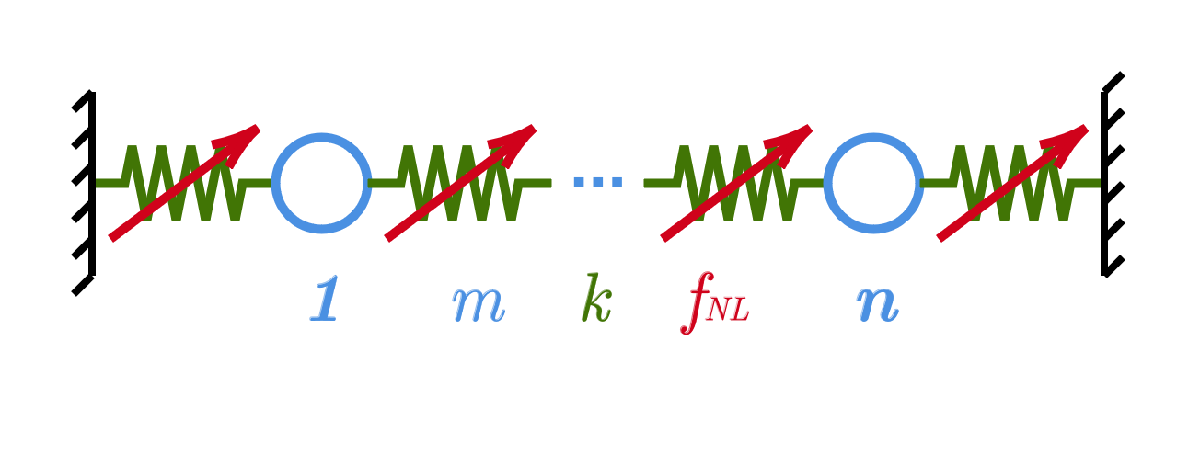

## Initialize

Include the function folder.

addpath(genpath(fullfile('..', 'LSM-opt-functions')))

## Settings

Define the type of the system.

sysArgs.systemType = @SystemSpringMassChainUniform;

Define the boundary conditions: 0 to fix the mas, 1 to let it free.

sysArgs.bc = [0, ones(1, 5), 0];

Define the index of the target mode.

sysArgs.modeIndex = 1;

Define the LSM arguments, i.e., the target dof of the system and the LSM expansion order.

lsmArgs.iDof = 3;
lsmArgs.order = 7;

## Optimization problem

The objective function and the nonlinear constraints are defined in the `fun` and `nonlcon` functions in this folder. 

Define the target points as frequency - amplitude pairs.

optArgs.omegaTarget = [2, 2.1];
optArgs.zTarget = [0, 2];

Specify if the frequency - amplitude pairs are treated as equality constraint (0), upper inequality constraint (1), or lower inequality constraint (-1).

optArgs.coeffTarget = [0, 0];

Define the initial conditions for the design variables.

x0 = [3, 30, 0, 3];

Define the lower and upper bounds for the design variables.

xl = [1, 10, 0.1, 0.1];
xu = [10, 50, 5, 5];

Define the linear equality and inequality constraints (if any).

A = []; b = [];
Aeq = []; beq = [];

## Optimizer options

In this work, `fmincon` is used to solve the nonlinear optimization problem.

Define below the required options

options = optimoptions('fmincon', 'Display', 'iter');
options.Algorithm = "interior-point";
options.EnableFeasibilityMode = true;
options.SpecifyObjectiveGradient = true;
options.SpecifyConstraintGradient = true;

## Solve the optimization problem

Solve and time the optimization problem

tStart = tic;
[x, fval] = fmincon(@(x) fun(x), x0, A, b, Aeq, beq, xl, xu, @(x) nonlcon(x, sysArgs, lsmArgs, optArgs), options);

Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.270000e+00    3.635e-01    1.074e+00
    1       2    3.058843e-01    9.985e-02    1.859e+00    1.520e+00
    2       3    4.576774e-01    5.810e-03    3.781e-01    2.670e-01
    3       4    3.791338e-01    2.632e-05    9.884e-02    3.291e-02
    4       5    2.879883e-01    9.767e-06    1.989e-02    3.917e-02
    5       6    2.700749e-01    3.699e-07    1.467e-02    1.289e-02
    6       7    2.696954e-01    3.056e-10    8.869e-03    4.895e-02
    7       8    2.675062e-01    5.826e-09    8.915e-03    2.444e-01
    8       9    2.565637e-01    1.605e-07    8.914e-03    1.222e+00
    9      10    2.019392e-01    6.971e-06    9.209e-03    6.097e+00
   10      11    1.345081e-01    4.291e-05    6.913e-01    7.521e+00
   11      13

tElapsed = toc(tStart);
disp(['Elapsed time is ', num2str(tElapsed, '%.2f'), ' seconds.'])

Elapsed time is 7.29 seconds.


## Post processing

Build the system and perform the eigenvalue analysis

sys = feval(sysArgs.systemType, x, sysArgs);
sys = sys.modal_analysis();

`Identify the master mode. In this case, it's the first one.`

sys.omega0 = sys.omega(sysArgs.modeIndex);
sys.phi0 = sys.phi(:, sysArgs.modeIndex);
sys = sys.state_space_modal_analysis();

Build the LSM.

lsm = LSM(sys, lsmArgs.order);
lsm = lsm.compute_manifold();

Compute the backbone points.

rhoTarget = lsm.solve_rho(optArgs.zTarget, lsmArgs.iDof);
rho = linspace(0, max(rhoTarget), 51);
z = lsm.compute_z(rho, lsmArgs.iDof);
omega = lsm.compute_omega(rho);

Plot the backbone curve with the target points.

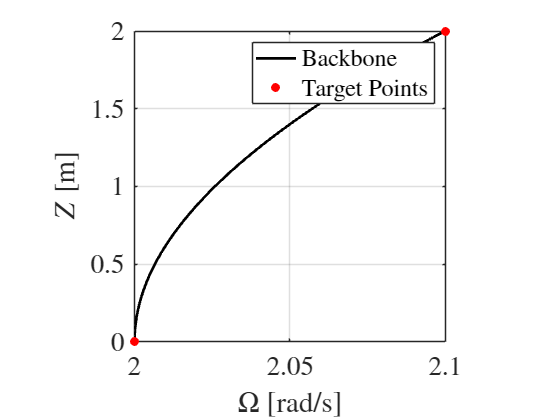

figure();
plot_backbone(omega, z, optArgs.omegaTarget, optArgs.zTarget);

## Numerical frequency response validation

Define the frequency limits the number of points.

omegaLim = [0.9, 1.1];
nOmega = 51;

Define the forcing amplitudes.

fExtNorm = [1, 2, 3];

Define the input and output dof indices.

iInput = 3;
iOutput = 3;

Define the Rayleigh damping coefficients.

rayleighDamping = [0, 0.02];

Compute the frequency sweeps (negative and positive).

[omegaNeg, omegaPos, zNeg, zPos] = sys.compute_numerical_frequency_response(omegaLim, nOmega, fExtNorm, iInput, iOutput, rayleighDamping, true);

Forcing amplitude 1 ... negative sweep ... positive sweep ... done in 8.0293 seconds.
Forcing amplitude 2 ... negative sweep ... positive sweep ... done in 9.6679 seconds.
Forcing amplitude 3 ... negative sweep ... positive sweep ... done in 11.1437 seconds.


Plot the sweeps.

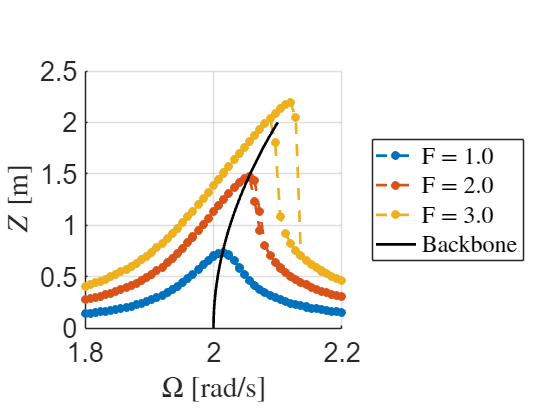

figure();
hold on; grid on;
legend_str = cell(length(fExtNorm) + 1, 1);
legend_str{end, 1} = 'Backbone';
for ii = 1:length(fExtNorm)
    legend_str{ii} = ['F = ', num2str(fExtNorm(ii), '%.1f')];
    OmegaFull = [omegaNeg, omegaPos];
    ZrmsFull = [zNeg{ii}, zPos{ii}];
    plot(OmegaFull, ZrmsFull, '.--', 'MarkerSize', 20, 'LineWidth', 2);
end
plot(omega, z, 'k', 'LineWidth', 2);
xlabel('$\Omega$ [rad/s]', 'Interpreter','latex')
ylabel('$Z$ [m]', 'Interpreter','latex')
legend(legend_str, 'Interpreter','latex', 'Location','eastoutside');
axis square
set(gca, 'FontSize', 20)